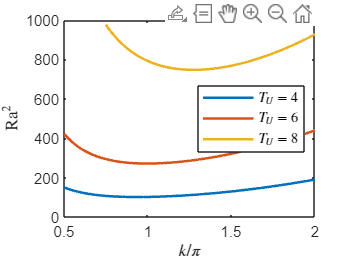

clear all
close all
clc
load sigma_TU=4.mat
TUTU1=[4 6 8];

for ind=1:length(TUTU1)
    TU=TUTU1(ind);
    if TU==4
        load sigma_TU=4.mat
    end
    if TU==5
        load sigma_TU=5.mat
    end
    if TU==6
        load sigma_TU=6.mat
    end
    if TU==7
        load sigma_TU=7.mat
    end
    if TU==8
        load sigma_TU=8.mat
    end
    if TU==4.5
        load sigma_TU=4.5.mat
    end
    if TU==5.5
        load sigma_TU=5.5.mat
    end
    if TU==6.5
        load sigma_TU=6.5.mat
    end
    if TU==7.5
        load sigma_TU=7.5.mat
    end
    l=1;
    l2=1;
    for j=1:length(kk)
        flag=0;
        n=1;
        while n<=length(RR)-1 && flag==0
            if (real(sigma(n,j))<0 && real(sigma(n+1,j))>0 && abs(imag(sigma(n+1,j)))<10^(-6)) || (real(sigma(n,j))>0 && real(sigma(n+1,j))<0 && abs(imag(sigma(n+1,j)))<10^(-6))
                if flag==0
                    realRa(l)=RR(n);
                    realwavenumber(l)=kk(j);
                    l=l+1;
                    flag=1;
                end
            end
            n=n+1;
        end
    end
    plot(realwavenumber,realRa.^2,LineWidth=1.5)
    xlabel('$k/\pi$',Interpreter='latex')
ylabel('$\mathrm{Ra}^2$',Interpreter='latex')
    hold on
    % [Rc,index]=min(realRa.^2);
    % wavec=realwavenumber(index);
    realRa=[];
    realwavenumber=[];

end
axis([0.5 2 0 1000])
legend('$T_U=4$','$T_U=6$','$T_U=8$',Interpreter='latex',Location='east')


% annotation('textbox',...
%     [0.291775981134712 0.0261137248498189 0.213494875549049 0.159754224270353],...
%     'String','$T_U=4, 4.5, 5, 5.5, 6, 6.5, 7, 7.5, 8$',...
%     'LineStyle','none',...
%     'Interpreter','latex',...
%     'FontSize',18,...
%     'FitBoxToText','off');